%% Random initialization + consensus with distance from robot

clear all
close all


% GRAPH/DIGRAPH #1/2
Gx=[20*rand(5,1)-10; 0]  % position x

Gx =     0.1127
    2.7132
    9.0179
   -1.1207
   -8.7996
         0


Gy=[20*rand(5,1)-10; 0] % position y

Gy =     7.3350
    2.6238
   -2.8985
    9.9401
   -5.5166
         0


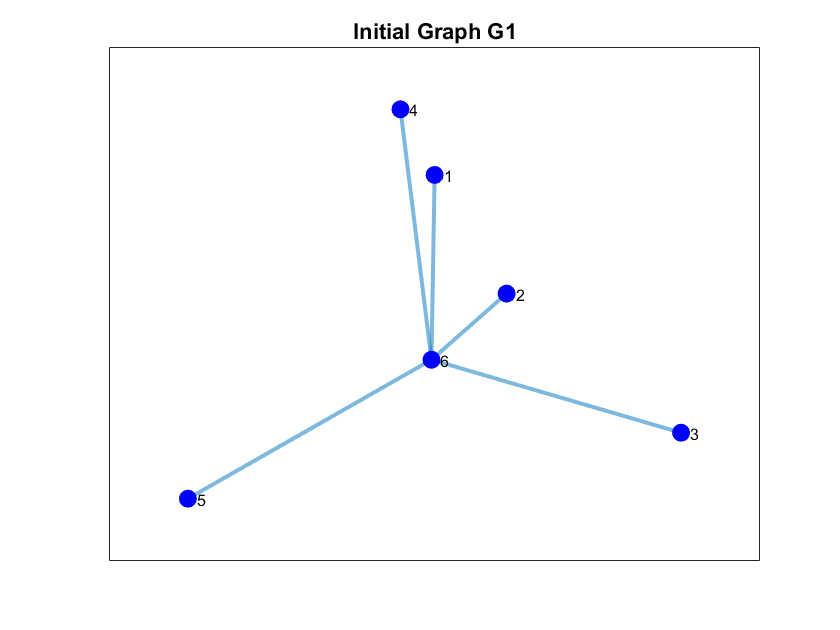


% GRAPH #1
edgesG1 = [ 1 6;
            2 6;
            3 6;
            4 6;
            5 6;];
figure; G1 = graph(edgesG1(:,1),edgesG1(:,2));
plot(G1,'XData',Gx,'YData',Gy,'MarkerSize',8,'NodeColor','b', 'LineWidth',2);
xticks([]); yticks([]); title('Initial Graph G1')

% two consensus matrices: 1 for rho (distance), 1 for theta (polar angle)

% itself=1/4;
% neighb=1/4;
% UGV=1-itself-2*neighb;
% P = [itself neighb  0   0  neighb UGV;
%      neighb itself neighb  0   0  UGV;
%       0  neighb itself neighb  0  UGV;
%       0   0  neighb itself neighb UGV;
%      neighb  0   0  neighb itself UGV;
%       0   0   0   0   0  1];

% P_rho = [1/2 0 0 0 0 1/2;
%          0 1/2 0 0 0 1/2;
%          0 0 1/2 0 0 1/2;
%          0 0 0 1/2 0 1/2;
%          0 0 0 0 1/2 1/2;
%          0 0 0 0 0 1];
P_theta = [ 1 1/2 0 0 -1/2 0;
            -1/2 1 1/2 0 0 0;
            0 -1/2 1 1/2 0 0;
            0 0 -1/2 1 1/2 0;
            1/2 0 0 -1/2 1 0;
            0 0 0 0 0 1];
%P_theta=eye(6);

% Polar coordinates
G_rho = [ 2*rand(5,1)+6; 0]

G_rho =     7.3049
    7.2100
    6.7745
    6.2844
    6.0503
         0


G_theta = [ 0 ; 0.628; 0.628*2; 0.628*3; 0.628*4; 0]

G_theta =          0
    0.6280
    1.2560
    1.8840
    2.5120
         0


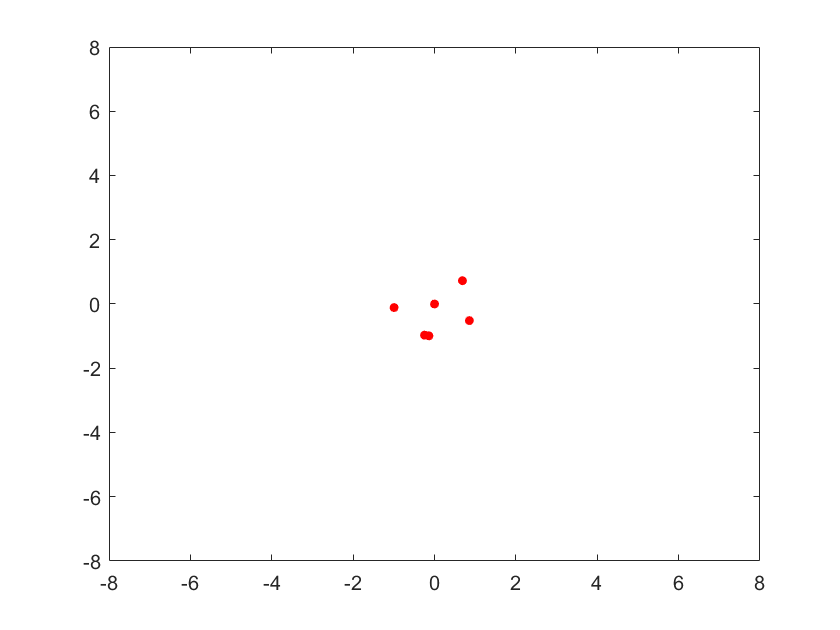

% n=20;
% 
% Gx_new = Gx;
% Gy_new = Gy;
% 
% for i=1:n
%     Gx_new = P*Gx;
%     Gy_new = P*Gy;
%     M = Gx_new*Gx_new.' + Gy_new*Gy_new.';
%     for j=1:5
%         if (sqrt(M(j,j)) > 0.5)
%             Gx(j) = Gx_new(j);
%             Gy(j) = Gy_new(j);
%         end
%     end
%     plot(Gx,Gy,'or','MarkerSize',4,'MarkerFaceColor','r')
%     axis([-5 5 -5 5])
%     pause(0.1)
% end

n=50;

G_rho_new = G_rho;

for i=1:n
    % Convert to cartesian coords
    Gx = [G_rho(1)*cos(G_theta(1));
        G_rho(2)*cos(G_theta(2));
        G_rho(3)*cos(G_theta(3));
        G_rho(4)*cos(G_theta(4));
        G_rho(5)*cos(G_theta(5));
        0];
    Gy = [G_rho(1)*sin(G_theta(1));
        G_rho(2)*sin(G_theta(2));
        G_rho(3)*sin(G_theta(3));
        G_rho(4)*sin(G_theta(4));
        G_rho(5)*sin(G_theta(5));
        0];
    plot(Gx,Gy,'or','MarkerSize',4,'MarkerFaceColor','r')
    axis([-8 8 -8 8])
    
    % P_rho defined as function of the error
    err_norm = 0.2*[(G_rho(1) - 1)/G_rho(1);
                    (G_rho(2) - 1)/G_rho(2);
                    (G_rho(3) - 1)/G_rho(3);
                    (G_rho(4) - 1)/G_rho(4);
                    (G_rho(5) - 1)/G_rho(5)];
    P_rho = [1-err_norm(1) 0 0 0 0 err_norm(1);
             0 1-err_norm(2) 0 0 0 err_norm(2);
             0 0 1-err_norm(3) 0 0 err_norm(3);
             0 0 0 1-err_norm(4) 0 err_norm(4);
             0 0 0 0 1-err_norm(5) err_norm(5);
             0 0 0 0 0 1];
    G_rho = P_rho*G_rho;
    G_theta = P_theta*G_theta;
    for j=1:4
        %theta
        if (G_theta(j) > 2*pi)
            G_theta(j) = G_theta(j)-2*pi;
        end
        if (G_theta(5) < 2*pi)
                G_theta(j) = G_theta(j)+2*pi;
        end
    end
    
    pause(0.2)
end